Music_lib_dir = "Music_Library/";
Music_ex_dir  = "Example_Library/";
Img_dir       = "Image_Library/"

Img_dir = "Image_Library/"

Music_Files = dir(fullfile(Music_lib_dir));



Musics_list = {length(Music_Files(:, 1)) - 2, 1};

max_length = -1

max_length = -1


for i = 3:length(Music_Files)
  baseFileName = Music_Files(i).name;  
  fullFileName = fullfile(Music_lib_dir, baseFileName);
  fprintf(1, 'Now reading %s\n', fullFileName);
  [y, fS] = audioread(fullFileName);   
  Musics_list{i - 2} = y;
 
  if length(y(:, 1)) > max_length
      max_length = length(y(:, 1));
  end
end

Now reading Music_Library\Beach_Gaelic Symphony_i. Allegro con fuoco.mp3
Now reading Music_Library\BeethovenSymphony5allegroconbrio.mp3
Now reading Music_Library\Beethovenpianosonata14mvt1adagio.mp3
Now reading Music_Library\Dvorak_Slavonic Dances, Op. 46, B. 83- I. Furiant. Presto in C Major.mp3
Now reading Music_Library\Dvorak_Slavonic Dances, Op. 46- No. 2 in E Minor.mp3
Now reading Music_Library\Hensel_Fanny_Notturno in G minor.mp3
Now reading Music_Library\Holmes_Irlande.mp3
Now reading Music_Library\Mendelssohn_Felix_A Midsummer Nights Dream Overture.mp3
Now reading Music_Library\Puccini_Madama Butterfly_Un bel di vedremo.mp3
Now reading Music_Library\Schumann_Clara_Piano Trio in G minor Op. 17 - I. Allegro moderato.mp3
Now reading Music_Library\Schumann_R_Frauenliebe_no1_Seit ich ihn gesehen.mp3
Now reading Music_Library\Schumann_R_Frauenliebe_no8_Now you have cased me pain.mp3
Now reading Music_Library\Sirmen_String Quartet No. 4 in B-Flat Major- II. Minuetto.mp3
Now reading Mu


for i = 3:length(Music_Files)
  figure_temp = figure,
  plot(y);
  saveas(figure_temp, Img_dir + i + ".jpg");
end



Music_Example      = dir(fullfile(Music_ex_dir));
Example_Filename   = fullfile(Music_ex_dir, Music_Example(3).name);
[Example_audio, ~] = audioread(Example_Filename);

size_diff = max_length - length(Example_audio(:, 1));

if size_diff > 0
    Example_audio = [Example_audio; ones(size_diff, 2)];
end

figure_example = figure,

figure_example =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


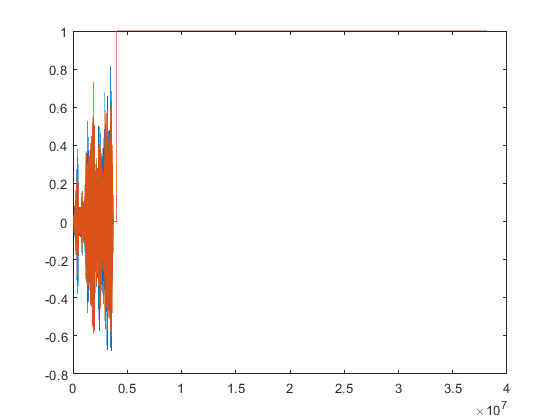

plot(Example_audio);
saveas(figure_example, Img_dir + "Example" + ".jpg");


Img_example_filename = Img_dir + "Example" + ".jpg";
max_similarity = -1;
max_idx        = -1;
for i = 3 : length(Music_Files)
    Img_lib_filename = Img_dir + i + ".jpg";
    [x, ~, ~, ~] = SurfFeaturepoints(Img_example_filename, Img_lib_filename, sig/100);

    if length(x) > max_similarity
        max_similarity = length(x);
        max_idx = i;
    end
    disp(length(x));
end

   177

   173

   112

   142

   144

   148

   199

   185

   136

   120

   108

   127

   147

   120





disp(max_idx);

     9




disp(Music_Files(9).name);

Holmes_Irlande.mp3
